addpath(genpath('../'))
set(0,'DefaultFigurePosition',[1200 800 580 406])
clear all
close all
clc

load('datasets/qanr1D_N2000_nu0.mat'); extrinsic_nz = 10^(-1.5);
% load('datasets/qanr1D_N2000.mat'); extrinsic_nz = 0;
% load('datasets/qanr1D_N2000_sigx.mat'); extrinsic_nz = 0;

## compute approximate particle distribution (Xscell, t)

exps = 1:4;
subsampN = 1;

numx = 256 + 1;
numsdv = 3;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
Xsnz = [extrinsic_nz 1];
scoord = 0;

NN = size(Xscell{1},1);
dim = size(Xscell{1},2)+1;

get_particle_distrib;

exps num does not exist,using available exps
ET_load_data = 0.1434 


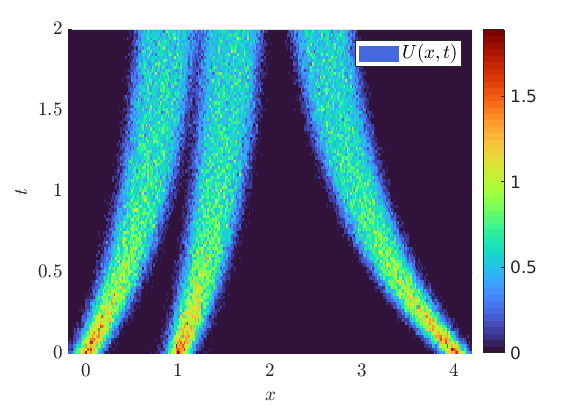

plotgap=1;
plot_distrib;

## choose model library

% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

% local non-autonomous operators
driftpolys=[0 2:8]; drifttrigs=[];
diffpolys=[0:8]; difftrigs=[]; crossdrift=1;

% non-local operators
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[0:6],'Sing',[],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 1.1932 


## Set Discretization

phi_class = {1,1};
sm_x = 5;
sm_t = 5;

## uncomment to set test fcn params manually

p_x = 5; mxs = 29;
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 8;
tau_t = []; k_t = []; tauhat_t = [];

% %%% set test fcn params using cornerpoint
% tauhat_x = 0.5; tau_x = 10^-6;
% p_x = []; mxs = 1;
% tauhat_t = 0.3; tau_t = 10^-3;
% p_t = []; mts = 1;

## rescale coordinates and/or use approx. variance for improved conditioning

scales = 2;
covtol = 0;

## trim rows with low particle density

trim_tags = [1 zeros(1,dim-1) 0];
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-inf;

set_discretization;

ET_setdisc = 1.1317 


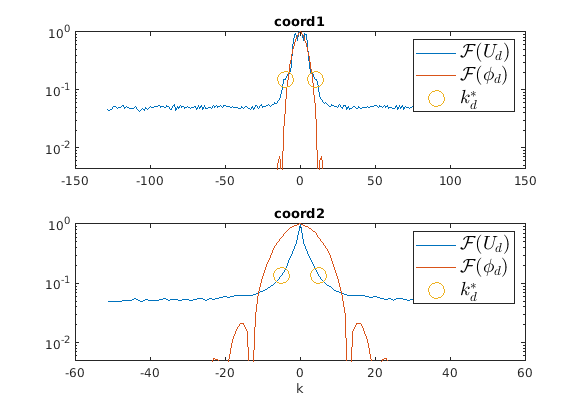


toggle_plot_fft = 1;
plot_Ufft;

## Build linear systems

build_Gb;

ET_build_Gb = 0.1386 


## MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags= {'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 1.9343 


## get_results

print_loc = 1;
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')
get_results;


Recovered PDE: u^{1}_{t} = -1.00832convmonx0 + 1.00377convmonx1
Relative Res: ||b-G*W||_2/||b||_2 = 3.31e-02
Max Weight Error: max|W-W_{true}| = 8.32e-03
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 29 8 
[s_x s_t] = 5 1 
[p_x p_t] = 5 3 
 scales = 1.00e+00 6.33e+00 6.25e+00 
      
Total particles = 2000 
Size of U = 256 101 
Size G = 3400 24 
Cond G = 8.32e+09
[lambda_hat gamma] = 1.048e-02 0.000e+00 
extrinsic noise ratio= 3.162e-02
STLS its = 7 
total elapsed time = 4.5411 


## Display loss

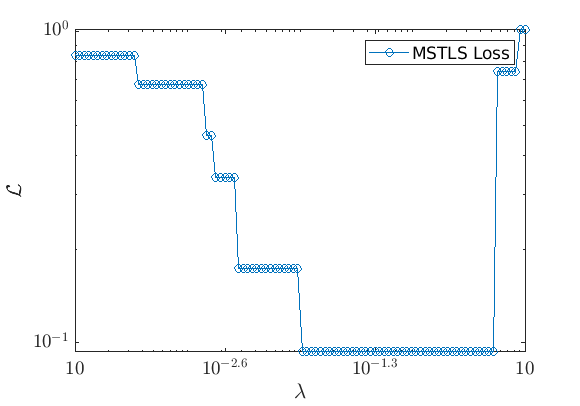

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

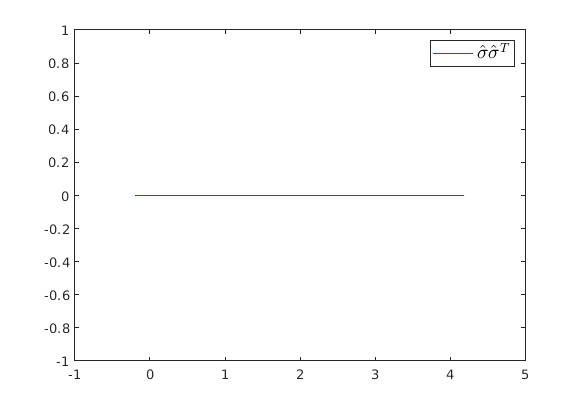


nu rel. err. 

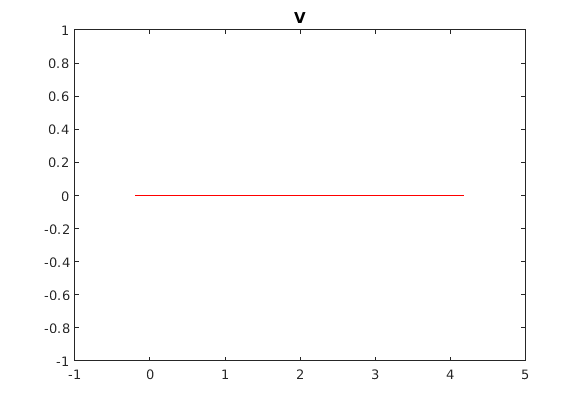

toggle_plot_drift = 1;
plot_driftdiff;

## Display interaction force

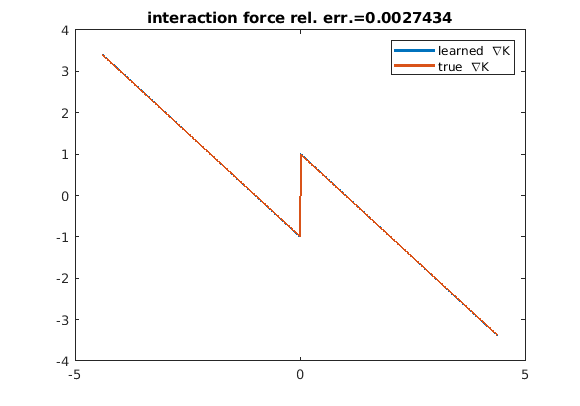

toggle_plot_IPforce = 1;
plot_K